# Machine repair scheduling

We have a machine that we use to print money. The condition of this machine can be in one of five states: **{new, good, normal, bad, broken}**, which naturally deteriorate over time. The amount of money the machine prints depends on its condition. If the machine is not in perfect condition (new), we can schedule a repair, that should put the machine into a better state, or we can buy a new machine. Our task is to come up with a plan of making repairs and buying new machines to maximize our profit over a fixed time period.


$$\[
x_0: \text{Initial machine state}, x_0 \in \{\text{new (1)}, \text{good (2)}, \text{normal (3)}, \text{bad (4)}, \text{broken (5)}\} 
\]
\[
N: \text{Number of time steps (days/weeks/months)}
\]
\[
x_k: \text{State of the machine at time } k = 1, \ldots, N
\]
\[
u_k: \text{Chosen action at time } k = 0,\ldots, N-1, u_k \in \{\text{do nothing (0)}, \text{repair (1)}, \text{buy new (2)}\}
\]
\[
w_k: \text{Machine deterioration at time } k, \text{depends on } x_k \text{ and } u_k
\]
$$


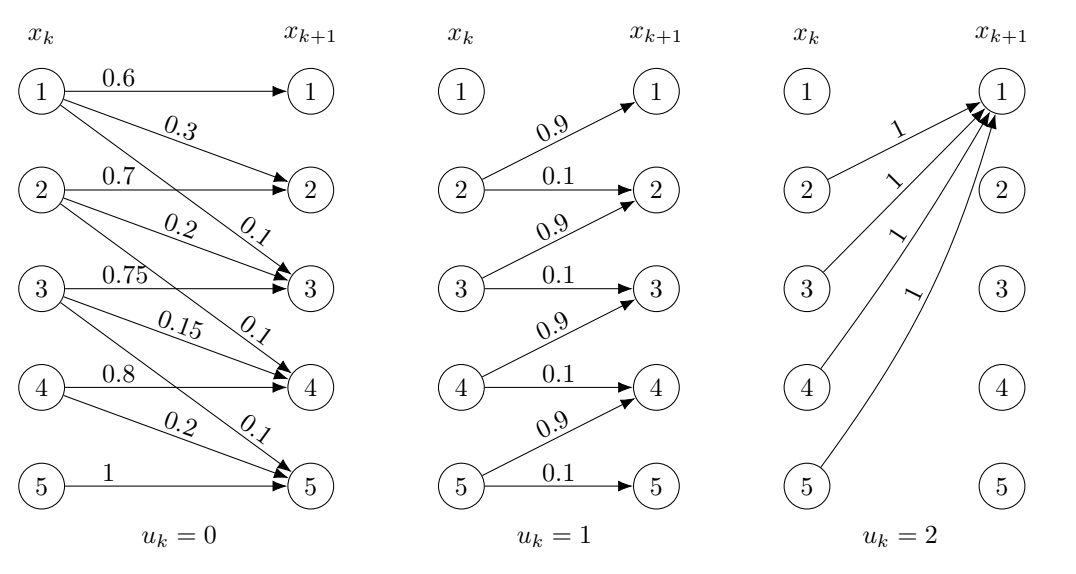


$$\[
\text{Amount of money printed } (g^p) \text{ and cost of actions } (g^a) \text{ at } k:
\]
\[
g^p(x_k) = 
\begin{cases}
    1,     & \text{for } x_k = 1, \\
    0.9,   & \text{for } x_k = 2, \\
    0.6,   & \text{for } x_k = 3, \\
    0.4,   & \text{for } x_k = 4, \\
    0,     & \text{for } x_k = 5,
\end{cases}
\qquad
g^a(u_k) = 
\begin{cases}
    0,   & \text{for } u_k = 0, \\
   -0.4, & \text{for } u_k = 1, \\
   -1,   & \text{for } u_k = 2.
\end{cases}
\]$$



$$\[\text{Profit at time } k \text{ and the final time } N:\]
\[
g_k(x_k, u_k) = g^p(x_k) + g^a(u_k), 
\qquad
g_N(x_N) = g^p(x_N)
\]$$



$$\[\textbf{Assignment:} \text{ Compute the optimal control for } x_0 = 1, N = 10,\text{while}\]
a) maximizing the expected profit: 
    \[
    E_w \left\{ g_N(x_N) + \sum_{k=0}^{N-1} g_k(x_k, u_k) \right\}
    \]
$$


xs = [1:5]'; us = [1:3]'; N =10;
W = zeros(5,5,3);

%u=1
W(1,1,1) = 0.6; W(1,2,1) = 0.3; W(1,3,1) = 0.1;
W(2,2,1) = 0.7; W(2,3,1) = 0.2; W(2,4,1) = 0.1;
W(3,3,1) = 0.75; W(3,4,1) = 0.15; W(3,5,1) = 0.1;
W(4,4,1) = 0.8; W(4,5,1) = 0.2;
W(5,5,1) = 1;

% u=2
W(2,1,2) = 0.9; W(2,2,2) = 0.1;
W(3,2,2) = 0.9; W(3,3,2) = 0.1;
W(4,3,2) = 0.9; W(4,4,2) = 0.1;
W(5,4,2) = 0.9; W(5,5,2) = 0.1;

% u=3
W(2:5,1,3) = 1;

g_p = [1, 0.9, 0.6, 0.4, 0];
g_a = [0,-0.4,-1];

J = zeros(5,N+1); mu=zeros(5,N);
J(:,N+1) = g_p;

for i=N:-1:1
    for ii=1:5
        x_cur = xs(ii);
        J_temp = zeros(3,1);
        for iii=1:3
            u_cur=us(iii);
            w_cur = W(x_cur,:,u_cur);
            if sum(w_cur) > 0
                J_temp(iii) = g_p(ii) + g_a(iii) + w_cur*J(:,i+1);
                % J_temp(iii) = g_p(ii) + g_a(iii) + min(J(w_cur>0,i+1));
            else
                J_temp(iii) = -Inf;
            end 
        end
        [maxval,maxpos] = max(J_temp);
        J(ii,i) = maxval; mu(ii,i)=us(maxpos);
    end
end

mu

mu =      1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     1
     2     2     2     2     2     2     2     2     2     1
     3     3     3     3     3     3     3     3     3     1
     3     3     3     3     3     3     3     3     3     1



%simulator
n = 1000; x0 = 1 ;
J_sim = zeros(n,1); x_sim=zeros(n,N+1); x_sim(:,1) = x0;
for iter = 1:n
    for i = 1:N
        x_cur = x_sim(iter,i);
        u_cur = mu(x_cur,i);
        J_sim(iter) = J_sim(iter) + g_p(x_cur) + g_a(u_cur);
        w = W(x_cur,:,u_cur);
        r = rand;
        idxs = find(r < cumsum(w));
        x_sim(iter,i+1) = idxs(1); 
    end
    J_sim(iter) = J_sim(iter) + g_p(x_sim(iter,end)); 
end

[min(J_sim), mean(J_sim), J(1,1)]

ans =     6.6000    9.1974    9.1695
